# Tuning PID controllers

## **Instructions **

- Note: This assignment does not require you to use Simulink

- Complete all the coding and reflection activities. 

## **Definitions relevant for this assignment**

The PID parameters can be tuned to improve the controller response. In the context of tuning PID controllers, understanding the time response characteristics of a system's step response is essential.  With a manual tuning approach, the controller gains are adjusted to improve several standard time-response characteristics. These characteristics help evaluate how effectively a PID controller manages the behavior of a system.The essential quantities are (for a step response):

- *Rise time*: Time it takes for the response curve $y(t)$ to rise from 10% to 90% of the steady-state value $y_\infty$.

- *Settling time*: Time it takes for the difference between the response curve $y(t)$ and the steady-state value $y_\infty$ to the fall below 2%.

- *Overshoot*: How far the peak value $y_{peak}$ overshoots $y_\infty$. This is often expressed as a percentage: $100\% \cdot (y_{peak} - y_\infty)/y_\infty$.

- *Peak time*: Time at which the peak value occurs.

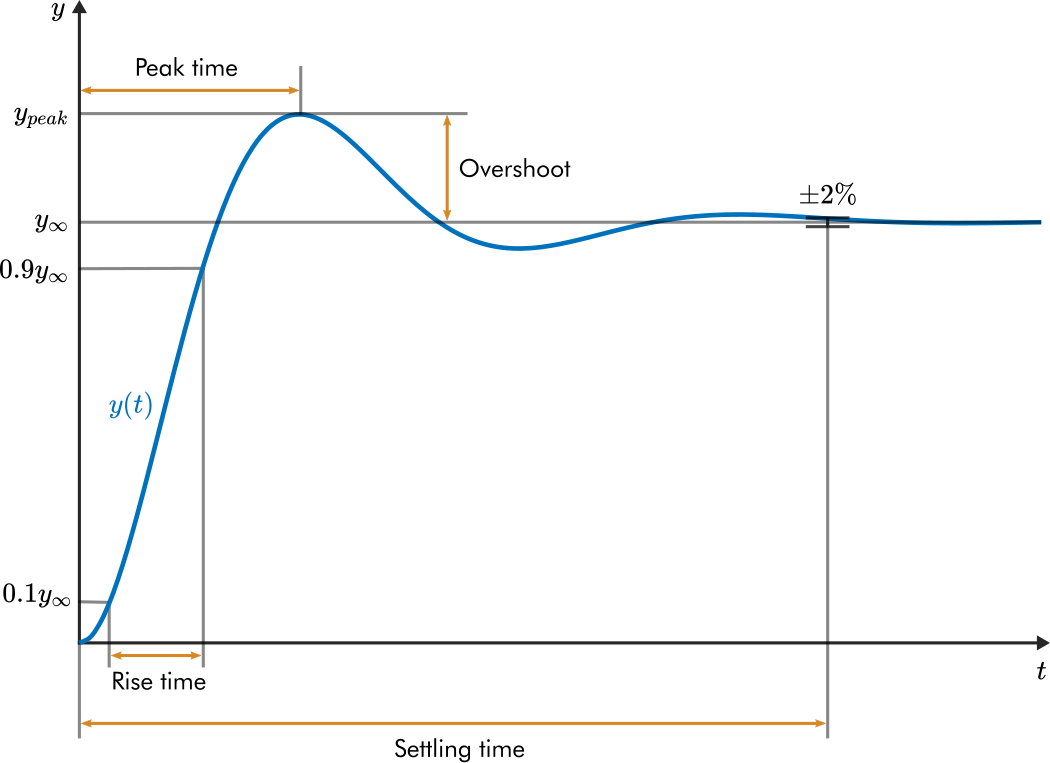

## Setting up the plant to be controlled

Our task begins with setting up a DC motor to serve as the plant for PID controller tuning. The primary objective is to control the angle of rotation of the motor's shaft. To achieve precise control, we must first establish a mathematical model of the DC motor, expressed as a transfer function. The transfer function of the DC motor will relate the input voltage to the angular position of the shaft, encapsulating the motor's dynamics. 

- Compute the transfer function model of the motor with angle output and store it in the variable DCmotorTF. The values of motor parameters have been set for you, please do not change these values.

%This part of the code sets up the transfer function equation for your
%convenience. You can use the expression to create your transfer function
%model using the tf function
syms L R k_e J B k_m    % Constants
syms Theta I s V        % Laplace domain variables
% Write your laplace transform equation here
eqn1 = V == R*I + s*L*I + k_e*s*Theta;
eqn2 = s^2*J*Theta + s*B*Theta == k_m*I ;
[ThetaSol, VSol] = solve([eqn1,eqn2],[Theta,V] );

ThetaOverV =  simplify(ThetaSol/VSol)
clear B K L R J
B = 0.028; K = 0.05; L = 0.1; R = 0.25;  J =  3.37e-5;
%write your code here 
DCmotorTF = NaN;

## Proportional (P) controller

We will now start building and tuning the controller by creating a transfer function for a closed-loop system. The feedback system is arranged as shown in the figure below.    For now, this system consists only of a proportional gain controller in series with the transfer function of the DC motor. 

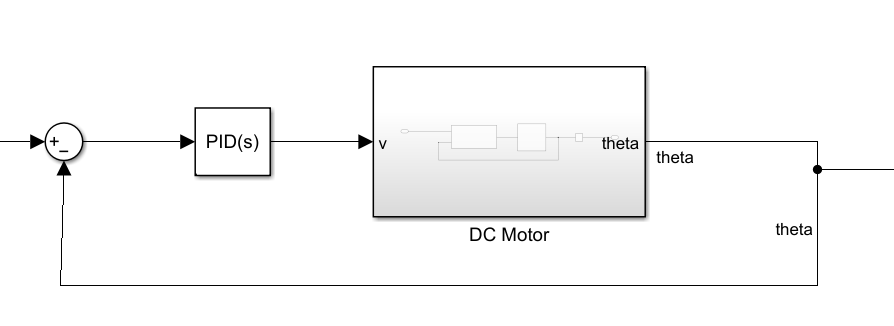

### Setting up the closed loop system

- Compute the transfer function model of the closed loop system where the input is the reference command and the output is the angle of rotation ($$\theta$$)  of the shaft, with $K_p=1$, and all other gains set to zero. Store the new transfer function in the variable `closedLoopSystem1`. 

- Plot the step response of the `closedLoopSystem1`.

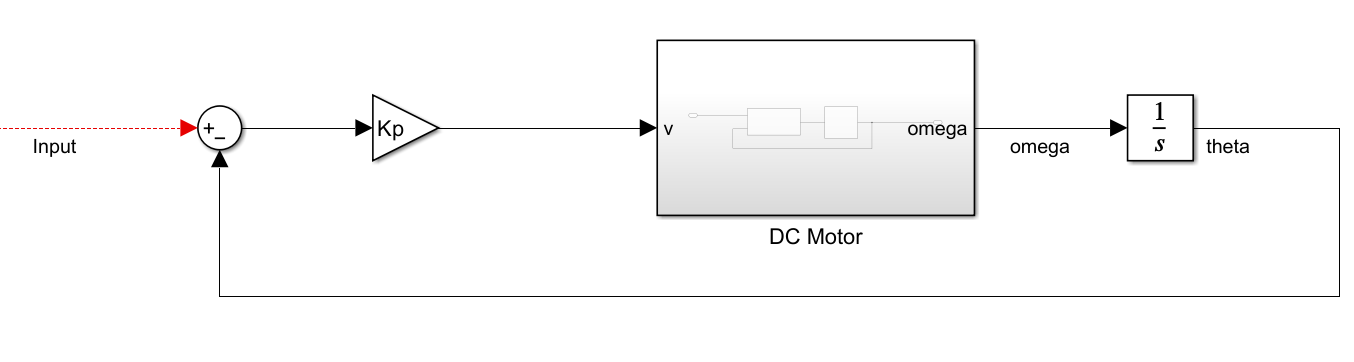

**Hint:** Use the `series()` and `feedback()` functions to compute this transfer function. 

%write your code here 
 
closedLoopSystem1 = NaN;

### Tuning proportional gain

Now, change the values of $K_p$ from 0.2 to 2 (with increments of 0.2) and observe the values of the poles. You will notice that there is one real pole with a high magnitude (and therefore will die out quickly in the transient response) and two complex poles with smaller maganitude. These two smaller poles will dominate the transient behavior. 

As you increase the $K_p$ values, observe how the pole values change and how the corresponding step response changes. (Note: you will have to compute a new transfer function for closedLoopSystem1 everytime you change $K_p$ values).

%write your code here 


**Reflect: **

- How does the rise time change in the step response with increasing $K_p$ values? 

- How does the frequency of oscillations and overshoot change with increasing $K_p$ values? 

- How is the change in frequency reflected in the pole values? 

Enter your answers here: 

## Proportional-Differential (PD) controller

Similar to previous section, we must first create a new closed loop system transfer function, this time including the differential gain. As we saw in the lecture, we will use a filtered derivative to implement the differentiator with the following transfer function 


$$\frac{100s}{s + 100}$$


- Store the new transfer function in the variable closedLoopSystem2 and use $K_d$= 0 and $K_p = 2$. 

- Plot the step response for closedLoopSystem1 and superimpose that for closedLoopSystem2 in the same figure. Note that these two responses should be the same as $K_d=0$ for now. 

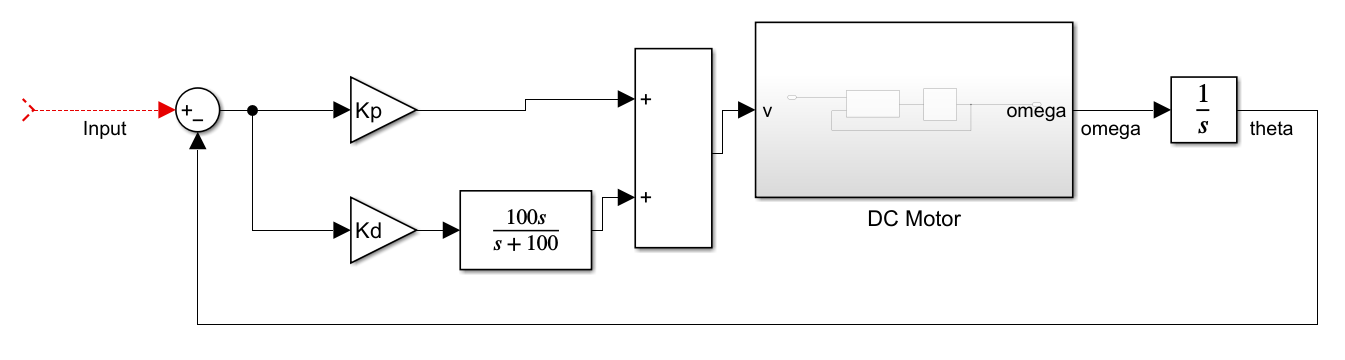

**Hint**: review the documentation for the function `parallel`

%write your code here 


### Tuning Differential gain 

- Change Kd values (between 0 and 0.5) and plot the 2 poles with the smallest magnitude (the last two poles returend by the pole() function) and observe how they move. For some values of $K_d$ you should be see complex poles, whereas for others, all real poles. 

- Plot the step response for closedLoopSystem1 and superimpose that for closedLoopSystem2 in the same figure as you ar changing the $K_d$ values. 

%write your code here 


**Reflect**

- What is the relationship between $K_d$ values and the damping observed in the step response? 

- What does the overshoot values change with $K_d$ values? 

- Is there a steady state error (zoom in to find out)? 

Enter your answers here: 

## Proportional-Integral-Differential (PID) controller

We will now include the integral gain of the PID controller. Compute and store the new transfer function in closedLoopSystem3.

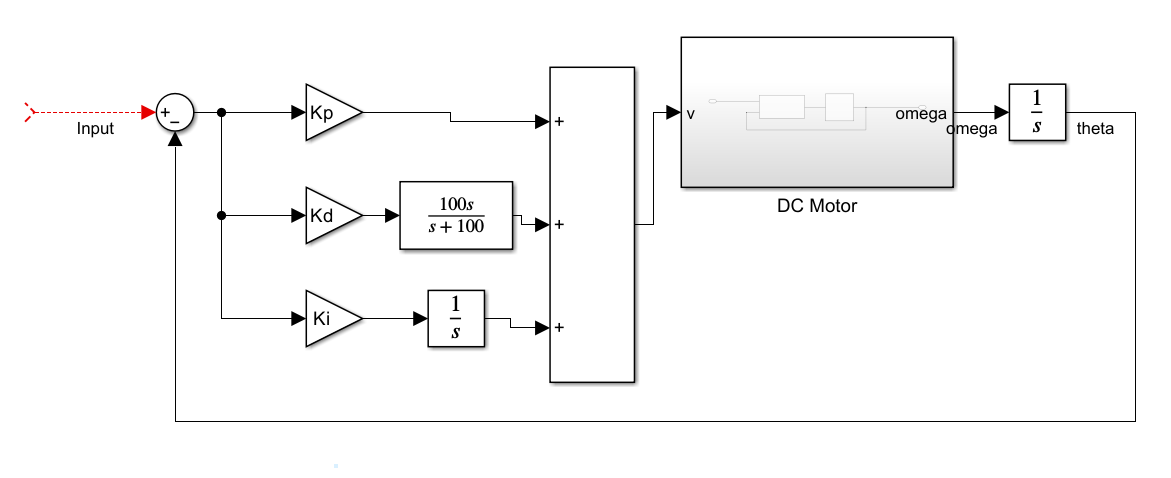

- Change the gain value $K_i$ between 0 and 1 and observe the step response and pole locations. 

- Plot the step response for closedLoopSystem2 and superimpose that for closedLoopSystem3 in the same figure as you ar changing the $K_i$ values. 

%write your code here 


**Reflect**

- Observe what is hapenning to the settling time as you increase $K_i$ values. 

- What is the steady state error? 

Enter your answers here: 

## General guidelines for tuning a PID

Based on the above exercise, do you agree with the gollowing general guidelines for tuning PID contollers? 

- Adjust Kp to according to the rise time, then adjust Kd according to the desired maximum overshoot, then adjust Ki according to the desired settling time. 

- Note: There will be limitations to how much you can achieve using PID controllers and these guidelines may not apply to all systems (especially higher order systems).